## Initial Runge-Kutta 4 method

Initial Runge-Kutta 4 implementation using a finer-step, so that a minimum precision is maintained.

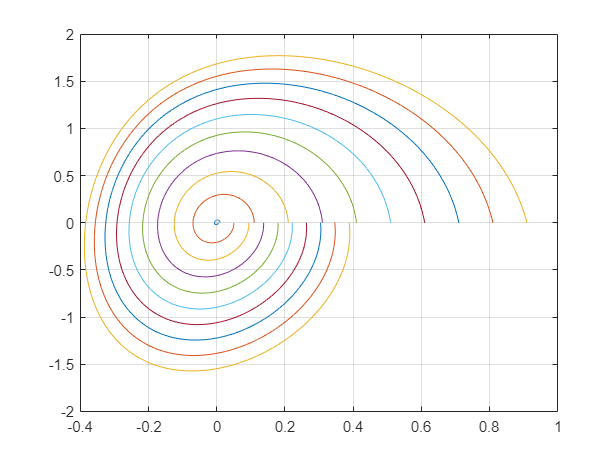

global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

% a1=1;b1=1;c1=0;al1=0;bt1=1;
% a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;



h=0.01;
x2=[];
T=[];
xdif=[];
j=1;
h=0.01;
for i=setdiff(1:10:100,0)
    x=[]; x(1) = i*h;
    y=[]; y(1) = 0;
    [x,y,T(j)] = RK4cycle(x,y,-0.001);
    x2(j)=i*h;
    xdif(j)=x(end)-x(1);
    j=j+1;
    plot(x,y);
    hold on
end
grid on
hold off

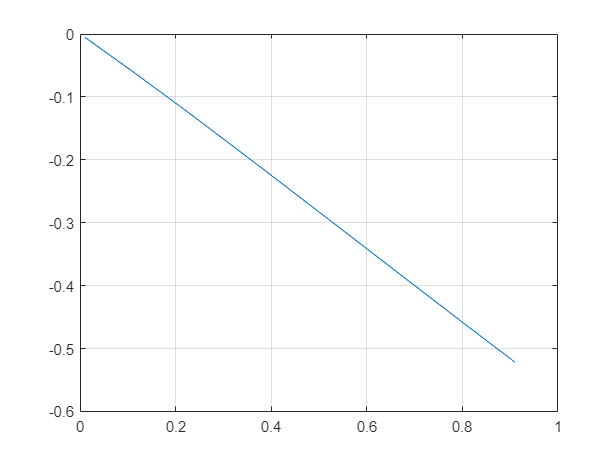

plot(x2,xdif);
grid on

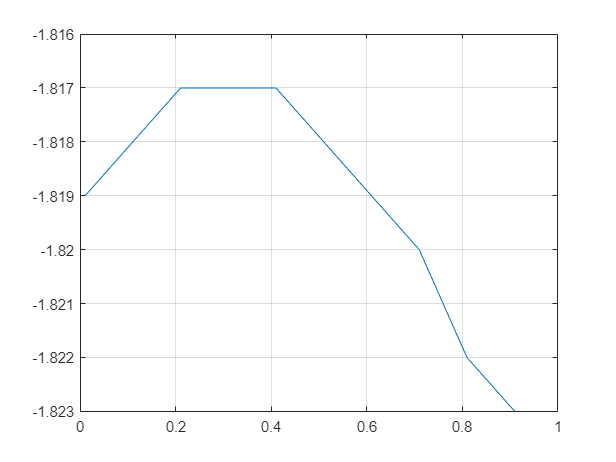

plot(x2,T);
grid on

## Functions

function [x,y,T] = RK4cycle(x,y,h)

    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    
    % ODE
    dxdt=@(t,x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(t,x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    
    % Runge-Kutta 4

        for i=1:1:2

            k1x=dxdt(i*h, x(i), y(i));
            k1y=dydt(i*h, x(i), y(i));
        
            k2x=dxdt(i*h+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
            k2y=dxdt(i*h+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        
            k3x=dxdt(i*h+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
            k3y=dxdt(i*h+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        
            k4x=dxdt(i*h+h, x(i)+h*k3x, y(i)+h*k3y);
            k4y=dxdt(i*h+h, x(i)+h*k3x, y(i)+h*k3y);
        
            x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
        
        end

        i=3;

        while y(i)*y(i-1)>0

            k1x=dxdt(h*i, x(i), y(i));
            k1y=dydt(h*i, x(i), y(i));
        
            k2x=dxdt(h*i+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
            k2y=dxdt(h*i+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        
            k3x=dxdt(h*i+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
            k3y=dxdt(h*i+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        
            k4x=dxdt(h*i+h, x(i)+h*k3x, y(i)+h*k3y);
            k4y=dxdt(h*i+h, x(i)+h*k3x, y(i)+h*k3y);
        
            x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
            i=i+1;
        end
        
        j=i;

        for i=i:1:i+2

            k1x=dxdt(i*h, x(i), y(i));
            k1y=dydt(i*h, x(i), y(i));
        
            k2x=dxdt(i*h+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
            k2y=dxdt(i*h+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        
            k3x=dxdt(i*h+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
            k3y=dxdt(i*h+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        
            k4x=dxdt(i*h+h, x(i)+h*k3x, y(i)+h*k3y);
            k4y=dxdt(i*h+h, x(i)+h*k3x, y(i)+h*k3y);
        
            x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
        
        end
        
        i=j+2;
        while y(i)*y(i-1)>0

            k1x=dxdt(h*i, x(i), y(i));
            k1y=dydt(h*i, x(i), y(i));
        
            k2x=dxdt(h*i+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
            k2y=dxdt(h*i+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        
            k3x=dxdt(h*i+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
            k3y=dxdt(h*i+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        
            k4x=dxdt(h*i+h, x(i)+h*k3x, y(i)+h*k3y);
            k4y=dxdt(h*i+h, x(i)+h*k3x, y(i)+h*k3y);
        
            x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
            i=i+1;
        end
        T=i*h;
end